# Quiz 2 correlation

% Ideal Data
t = [1:1000]

t =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x = t

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


y = -t

y =     -1    -2    -3    -4    -5    -6    -7    -8    -9   -10   -11   -12   -13   -14   -15   -16   -17   -18   -19   -20   -21   -22   -23   -24   -25   -26   -27   -28   -29   -30   -31   -32   -33   -34   -35   -36   -37   -38   -39   -40   -41   -42   -43   -44   -45   -46   -47   -48   -49   -50


z = zeros(size(t))

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



x = sin(t*(3/17))

x =     0.1756    0.3457    0.5050    0.6487    0.7722    0.8718    0.9442    0.9874    0.9998    0.9813    0.9322    0.8542    0.7496    0.6218    0.4746    0.3127    0.1411   -0.0349   -0.2098   -0.3782   -0.5348   -0.6748   -0.7939   -0.8883   -0.9552   -0.9923   -0.9986   -0.9739   -0.9190   -0.8355   -0.7261   -0.5941   -0.4436   -0.2794   -0.1065    0.0697    0.2437    0.4102    0.5640    0.7002    0.8146    0.9038    0.9649    0.9960    0.9962    0.9654    0.9047    0.8158    0.7017    0.5657


y = -sin(t*(3/17))

y =    -0.1756   -0.3457   -0.5050   -0.6487   -0.7722   -0.8718   -0.9442   -0.9874   -0.9998   -0.9813   -0.9322   -0.8542   -0.7496   -0.6218   -0.4746   -0.3127   -0.1411    0.0349    0.2098    0.3782    0.5348    0.6748    0.7939    0.8883    0.9552    0.9923    0.9986    0.9739    0.9190    0.8355    0.7261    0.5941    0.4436    0.2794    0.1065   -0.0697   -0.2437   -0.4102   -0.5640   -0.7002   -0.8146   -0.9038   -0.9649   -0.9960   -0.9962   -0.9654   -0.9047   -0.8158   -0.7017   -0.5657



dataIdeal = [x; y; z]

dataIdeal =     0.1756    0.3457    0.5050    0.6487    0.7722    0.8718    0.9442    0.9874    0.9998    0.9813    0.9322    0.8542    0.7496    0.6218    0.4746    0.3127    0.1411   -0.0349   -0.2098   -0.3782   -0.5348   -0.6748   -0.7939   -0.8883   -0.9552   -0.9923   -0.9986   -0.9739   -0.9190   -0.8355   -0.7261   -0.5941   -0.4436   -0.2794   -0.1065    0.0697    0.2437    0.4102    0.5640    0.7002    0.8146    0.9038    0.9649    0.9960    0.9962    0.9654    0.9047    0.8158    0.7017    0.5657
   -0.1756   -0.3457   -0.5050   -0.6487   -0.7722   -0.8718   -0.9442   -0.9874   -0.9998   -0.9813   -0.9322   -0.8542   -0.7496   -0.6218   -0.4746   -0.3127   -0.1411    0.0349    0.2098    0.3782    0.5348    0.6748    0.7939    0.8883    0.9552    0.9923    0.9986    0.9739    0.9190    0.8355    0.7261    0.5941    0.4436    0.2794    0.1065   -0.0697   -0.2437   -0.4102   -0.5640   -0.7002   -0.8146   -0.9038   -0.9649   -0.9960   -0.9962   -0.9654   -0.9047   -0.8158   -0.7


%add gausian white noise
xn = awgn(x,.5)

xn =     0.5453    0.2140    1.0130    0.2506    0.8032    0.1174    1.9530    1.2718    2.7163   -0.7363    1.1547    0.7604    0.7815    0.1622    0.8434   -0.4784    0.4332    0.0014    0.1848    0.1587   -2.5819   -1.7446    0.1395   -2.2428   -0.1191   -1.2208    1.3408   -1.5471    0.7670   -3.5199   -2.9314    0.7163    0.0719    0.5220   -1.7607   -0.3964    0.7690    1.3682    1.0548    0.1566    1.0295    0.1809    2.8011    0.2171    1.8392   -0.0346    1.5212    2.3013    0.3086    1.8958


yn = awgn(y,.5)

yn =    -2.3879    0.0280   -0.7204    0.0025   -0.9830   -0.4106    1.0252   -2.3152   -0.8755   -1.3098   -0.7503   -1.2116   -0.5372   -1.1349    0.5542   -1.4489   -1.7069    0.9814    0.5930    2.3623    1.1872    0.4817   -0.3048    0.1232    1.4565    0.2221    1.4135    0.4487    2.2002    1.1783    0.5252   -0.6337    0.6936    1.1708    0.4754    0.0160    0.1010   -0.1822   -0.9046   -1.4545   -0.1688   -1.4628   -3.0690   -0.5281   -1.5801   -0.5231   -2.2073   -0.2065   -1.2211   -0.4997


zn = awgn(z,.5)

zn =    -0.0011    0.0203    0.3667   -1.1113    1.3698    0.3298   -0.6700   -0.1900   -0.2022   -0.2507    0.4489    0.1771   -0.6474    1.2431   -0.9593   -0.2680    0.8555    0.9955    1.0243    1.4424   -0.9044    0.0885   -0.4563    0.9453    0.1483   -0.9164    0.0174    1.7081    0.8731    0.0587   -1.3059   -1.0620   -0.8632   -0.0688   -0.2276   -0.2933    0.5483   -0.0871    0.6630   -0.9093   -0.9780    1.0226    0.6863   -0.8137   -1.3822   -1.7627   -0.2310   -0.2030    0.2736    0.5234



dataNoisy = [xn; yn; zn]

dataNoisy =     0.5453    0.2140    1.0130    0.2506    0.8032    0.1174    1.9530    1.2718    2.7163   -0.7363    1.1547    0.7604    0.7815    0.1622    0.8434   -0.4784    0.4332    0.0014    0.1848    0.1587   -2.5819   -1.7446    0.1395   -2.2428   -0.1191   -1.2208    1.3408   -1.5471    0.7670   -3.5199   -2.9314    0.7163    0.0719    0.5220   -1.7607   -0.3964    0.7690    1.3682    1.0548    0.1566    1.0295    0.1809    2.8011    0.2171    1.8392   -0.0346    1.5212    2.3013    0.3086    1.8958
   -2.3879    0.0280   -0.7204    0.0025   -0.9830   -0.4106    1.0252   -2.3152   -0.8755   -1.3098   -0.7503   -1.2116   -0.5372   -1.1349    0.5542   -1.4489   -1.7069    0.9814    0.5930    2.3623    1.1872    0.4817   -0.3048    0.1232    1.4565    0.2221    1.4135    0.4487    2.2002    1.1783    0.5252   -0.6337    0.6936    1.1708    0.4754    0.0160    0.1010   -0.1822   -0.9046   -1.4545   -0.1688   -1.4628   -3.0690   -0.5281   -1.5801   -0.5231   -2.2073   -0.2065   -1.2


% calculate correlation
rho_x =corrcoef(x,t)

rho_x =     1.0000   -0.0250
   -0.0250    1.0000


rho_y = corrcoef(y,t)

rho_y =     1.0000    0.0250
    0.0250    1.0000


rho_z = corrcoef(z,t)

rho_z =    NaN   NaN
   NaN     1


rho = [rho_x, rho_y, rho_z]

rho =     1.0000   -0.0250    1.0000    0.0250       NaN       NaN
   -0.0250    1.0000    0.0250    1.0000       NaN    1.0000



rho_xn = corrcoef(xn,t)

rho_xn =     1.0000   -0.0616
   -0.0616    1.0000


rho_yn = corrcoef(yn,t)

rho_yn =     1.0000    0.0485
    0.0485    1.0000


rho_zn = corrcoef(zn,t)

rho_zn =     1.0000    0.0007
    0.0007    1.0000


rho_n = [rho_xn, rho_yn, rho_zn]

rho_n =     1.0000   -0.0616    1.0000    0.0485    1.0000    0.0007
   -0.0616    1.0000    0.0485    1.0000    0.0007    1.0000


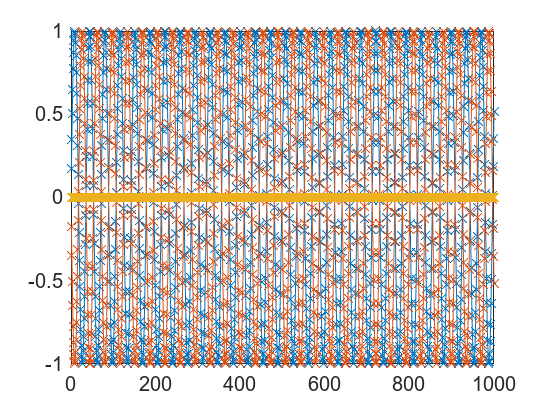


figure;
plot(t,dataIdeal,'-x')

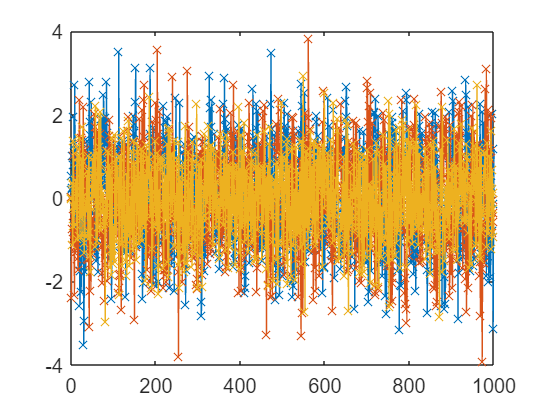


figure;
plot(t,dataNoisy,'-x')



%add gausian white noise
xn = awgn(x,2)

xn =    -0.5023    1.7439    1.0784    1.0740    0.6788    0.9809    0.8276    1.5601    1.7489    1.9458   -0.1258    1.4186    0.5571    0.4849    0.3684   -1.1737   -1.0795   -0.3916    0.5126    0.0374   -0.3806   -0.3632   -1.6829   -0.3195    0.0523   -1.0618   -1.5606   -0.7361    0.1469    0.4685   -0.9902   -0.2329   -0.7628    1.1009   -1.3699    1.9681   -0.6264    0.0207    0.4823    1.1247    1.4496    1.3303    0.1514    1.3014    0.8366    0.8748   -0.0456   -0.0866   -0.3924   -0.4283


yn = awgn(y,2)

yn =    -0.0860    0.5836   -1.2071    0.1338   -3.1096   -0.5990   -1.1092    0.8659   -0.9136   -1.5670   -1.4134   -0.0967   -0.2160   -0.3597   -0.5408   -0.8462   -0.0669    0.0771   -0.1380    1.8392    1.4079    0.5445    1.3257   -0.1518    1.6662    0.8617    0.2599    2.4858    1.2237    0.7624    1.4333    0.9548    0.8740    0.2655   -0.7211   -0.2458   -0.4712   -0.6486   -0.4353   -2.2206   -1.1300   -1.3490   -0.6323   -0.0843   -1.0175   -2.0241   -0.5497   -1.6957   -1.5864    0.0894


zn = awgn(z,2)

zn =    -1.1433   -0.5154   -0.3305    0.9670    0.9175    0.0412    0.0695   -0.2705   -0.4735    1.4797   -0.6331   -0.0777    1.0618   -0.4062   -0.6706   -1.4136    0.9761    0.3321   -0.4801    0.1835    2.3883    0.0269   -1.8605    0.3721   -0.1627   -1.3772    0.0782    0.2886    0.0486    0.3131    0.7862    0.0557    0.6134   -1.2531   -0.3991   -1.3193   -0.5328    0.6450   -1.2618   -0.5300   -1.5865    0.8897    0.4115    0.7601   -0.0227    0.3948   -0.6661    0.5256   -1.1377    0.5834



dataNoisy = [xn; yn; zn]

dataNoisy =    -0.5023    1.7439    1.0784    1.0740    0.6788    0.9809    0.8276    1.5601    1.7489    1.9458   -0.1258    1.4186    0.5571    0.4849    0.3684   -1.1737   -1.0795   -0.3916    0.5126    0.0374   -0.3806   -0.3632   -1.6829   -0.3195    0.0523   -1.0618   -1.5606   -0.7361    0.1469    0.4685   -0.9902   -0.2329   -0.7628    1.1009   -1.3699    1.9681   -0.6264    0.0207    0.4823    1.1247    1.4496    1.3303    0.1514    1.3014    0.8366    0.8748   -0.0456   -0.0866   -0.3924   -0.4283
   -0.0860    0.5836   -1.2071    0.1338   -3.1096   -0.5990   -1.1092    0.8659   -0.9136   -1.5670   -1.4134   -0.0967   -0.2160   -0.3597   -0.5408   -0.8462   -0.0669    0.0771   -0.1380    1.8392    1.4079    0.5445    1.3257   -0.1518    1.6662    0.8617    0.2599    2.4858    1.2237    0.7624    1.4333    0.9548    0.8740    0.2655   -0.7211   -0.2458   -0.4712   -0.6486   -0.4353   -2.2206   -1.1300   -1.3490   -0.6323   -0.0843   -1.0175   -2.0241   -0.5497   -1.6957   -1.5

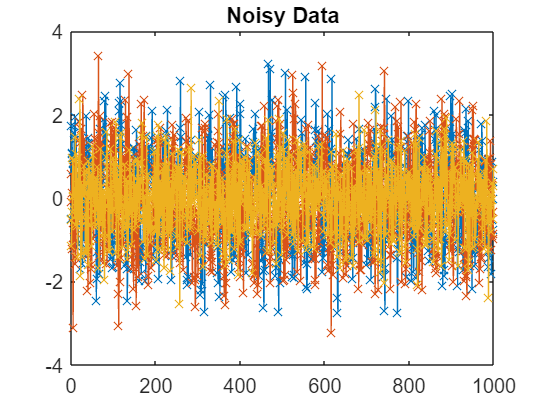

figure;
plot(t,dataNoisy,'-x')
title("Noisy Data")

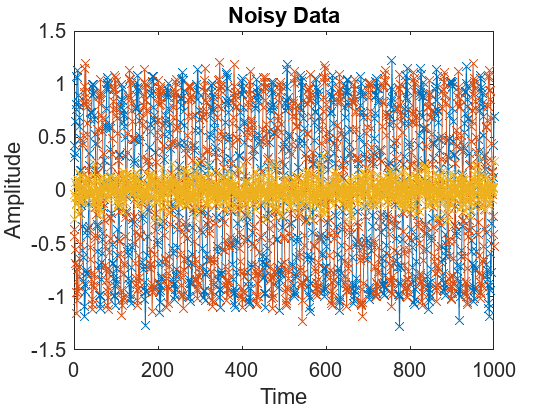

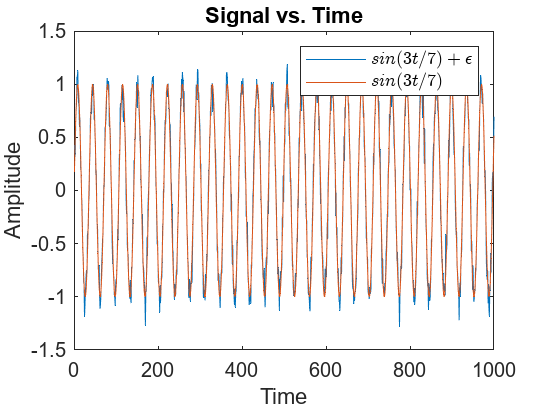

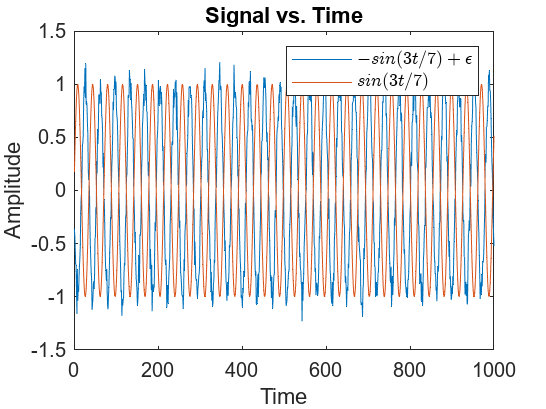

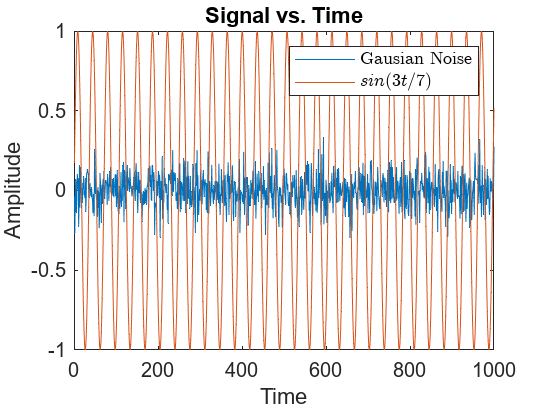

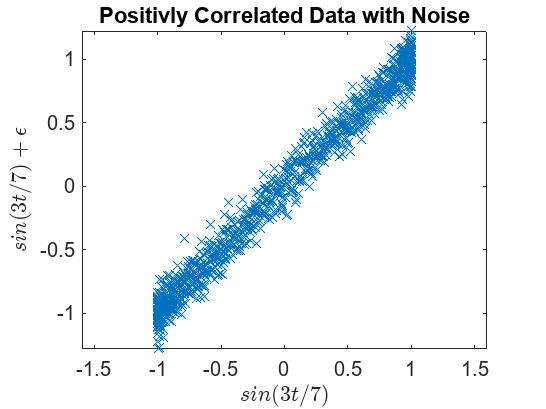

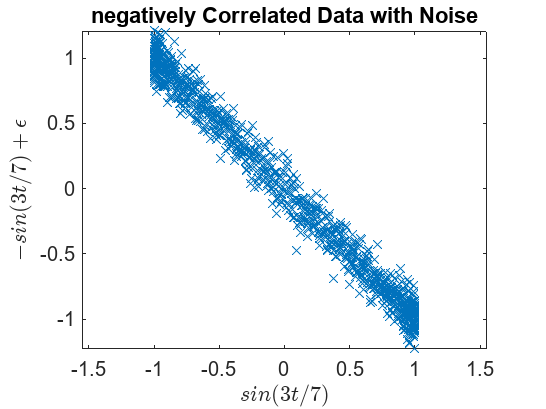

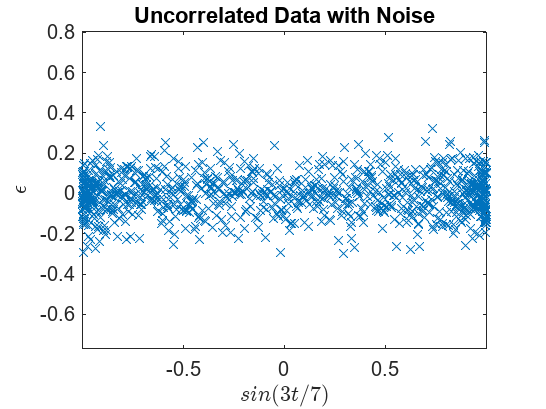

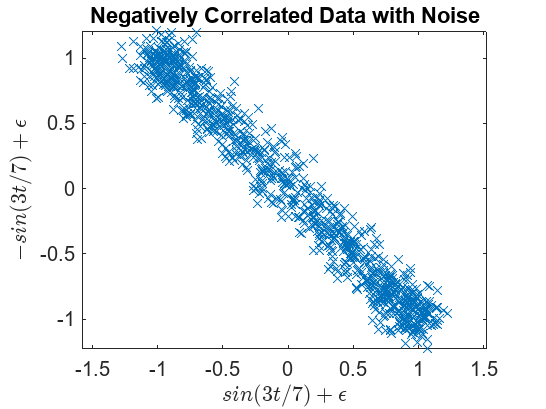

ans =     0.9905   -0.9905    0.0152   -0.9804    0.0095



plotsAndCorrelation(dataIdeal,t,20,true)



%noiseLevels = [2,3,5,10,20,50];
noiseLevels = linspace(0,50,1000)

noiseLevels =          0    0.0501    0.1001    0.1502    0.2002    0.2503    0.3003    0.3504    0.4004    0.4505    0.5005    0.5506    0.6006    0.6507    0.7007    0.7508    0.8008    0.8509    0.9009    0.9510    1.0010    1.0511    1.1011    1.1512    1.2012    1.2513    1.3013    1.3514    1.4014    1.4515    1.5015    1.5516    1.6016    1.6517    1.7017    1.7518    1.8018    1.8519    1.9019    1.9520    2.0020    2.0521    2.1021    2.1522    2.2022    2.2523    2.3023    2.3524    2.4024    2.4525


rhos = zeros(length(noiseLevels),size(dataIdeal,1)+2)

rhos =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


for i = 1:length(noiseLevels)
    noiseLevel = noiseLevels(i);
    rhos(i,:) = plotsAndCorrelation(dataIdeal,t,noiseLevel,false);
end

## plot correlations

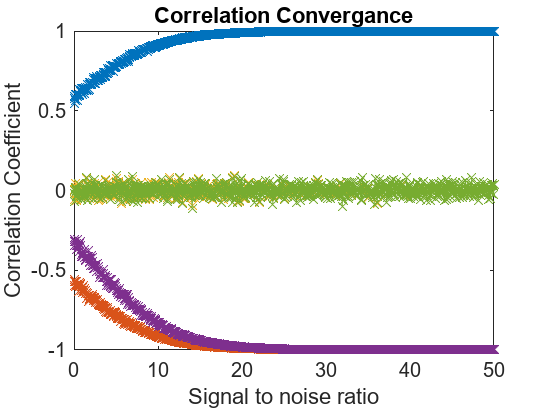

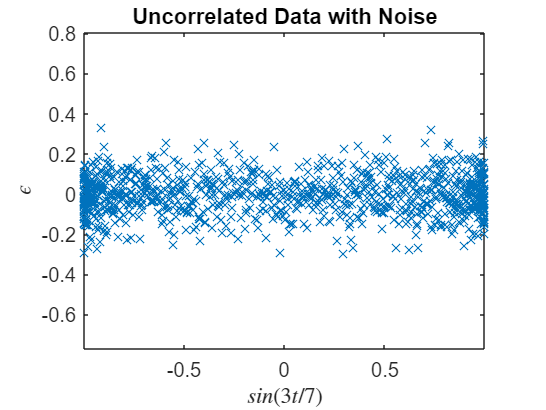

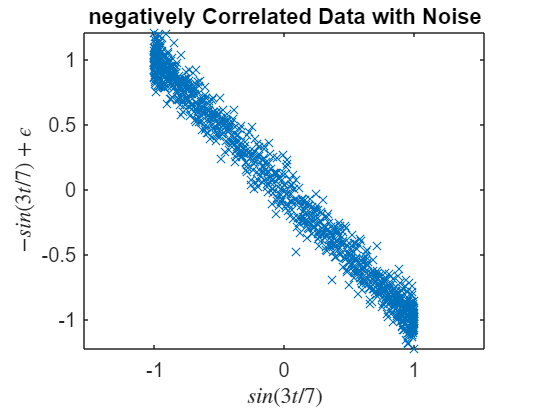

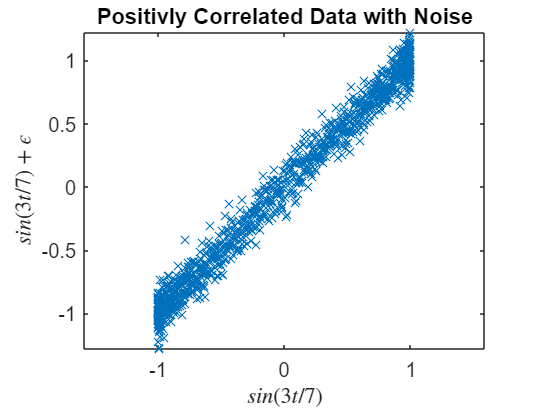

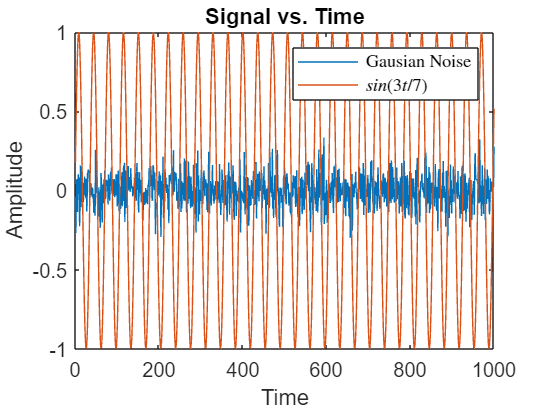

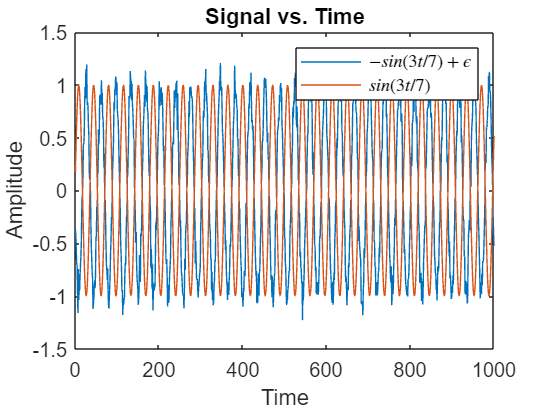

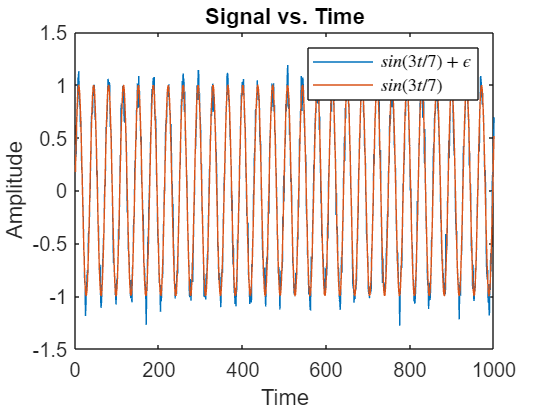

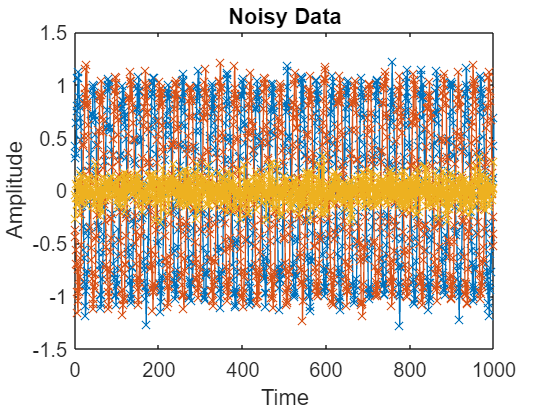


plot(noiseLevels,rhos,'-x')
title("Correlation Convergance");
ylabel("Correlation Coefficient");
xlabel("Signal to noise ratio");

saveAllFig('CorrelationFigs')

function rhos = plotsAndCorrelation(dataIdeal,t,noiseMagnitudeDB,plotResults)

## add gausian white noise

dataNoisy = awgn(dataIdeal,noiseMagnitudeDB);

if(plotResults)
    figure;
    plot(t,dataNoisy,'-x');
    title("Noisy Data")
    xlabel("Time")
    ylabel("Amplitude")
end

## Calculate Correlations

corrcoefs = corrcoef(dataIdeal(1,:), dataNoisy(1,:));
rho_pos = corrcoefs(1,2);
corrcoefs = corrcoef(dataIdeal(1,:), dataNoisy(2,:));
rho_neg = corrcoefs(1,2);
corrcoefs = corrcoef(dataIdeal(1,:), dataNoisy(3,:));
rho_un = corrcoefs(1,2);
corrcoefs = corrcoef(dataNoisy(1,:), dataNoisy(2,:));
rho_neg2 = corrcoefs(1,2);
corrcoefs = corrcoef(dataNoisy(1,:), dataNoisy(3,:));
rho_un2 = corrcoefs(1,2);
rhos = [rho_pos,rho_neg,rho_un,rho_neg2,rho_un2];

## plot signals vs Time

if(plotResults)
    plotSingalVTime(t,[dataNoisy(1,:); dataIdeal(1,:)],"$sin(3t/7)+\epsilon$")
    plotSingalVTime(t,[dataNoisy(2,:); dataIdeal(1,:)],"$-sin(3t/7)+\epsilon$")
    plotSingalVTime(t,[dataNoisy(3,:); dataIdeal(1,:)],"Gausian Noise")
end

## plot signal vs signal w/ noise

if(plotResults)
    figure;
    plot1 = plot(dataIdeal(1,:)',dataNoisy(1,:)','x');
    ylabel('$sin(3t/7) + \epsilon$','Interpreter','latex');
    xlabel('$sin(3t/7)$','Interpreter','latex');
    title("Positivly Correlated Data with Noise");
    axis equal
    
    figure;
    plot1 = plot(dataIdeal(1,:)',dataNoisy(2,:)','x');
    ylabel('$-sin(3t/7) + \epsilon$','Interpreter','latex');
    xlabel('$sin(3t/7)$','Interpreter','latex');
    title("negatively Correlated Data with Noise");
    axis equal
    
    figure;
    plot1 = plot(dataIdeal(1,:)',dataNoisy(3,:)','x');
    ylabel('$\epsilon$','Interpreter','latex');
    xlabel('$sin(3t/7)$','Interpreter','latex');
    title("Uncorrelated Data with Noise");
    axis equal
    
    %% noisy correlation to noisy plots
    figure;
    plot1 = plot(dataNoisy(1,:)',dataNoisy(2,:)','x');
    ylabel('$-sin(3t/7) + \epsilon$','Interpreter','latex');
    xlabel('$sin(3t/7) + \epsilon$','Interpreter','latex');
    title("Negatively Correlated Data with Noise");
    axis equal
    
    figure;
    plot1 = plot(dataNoisy(1,:)',dataNoisy(3,:)','x');
    ylabel('$\epsilon$','Interpreter','latex');
    xlabel('$sin(3t/7) + \epsilon$','Interpreter','latex');
    title("Uncorrelated Data with Noise");
    axis equal
end
end